# Retinal Blood Vessel Segmentation using MATLAB

clc;
clear;
close all;

## Loading & Plotting the raw imput image & ground truth image

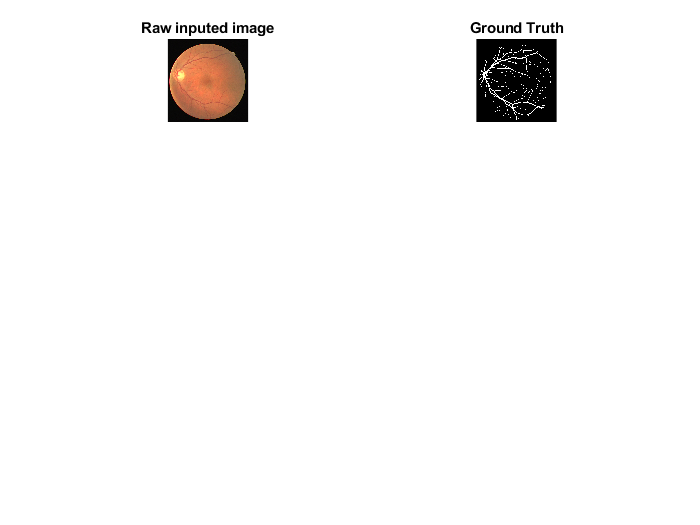

inputImage = imread('Data_Set/21_training.tif');
groundTruth = imread('Data_Set/21_manual1.gif');

subplot 421
imshow(inputImage);
title("Raw inputed image");

subplot 422
imshow(groundTruth);
title("Ground Truth");

%Vessel Extraction of retinal fundus Image using principal curvature
%inputImage : input retinal fundus image
%output - segImage : Segmented binary image 

## Generation of image mask

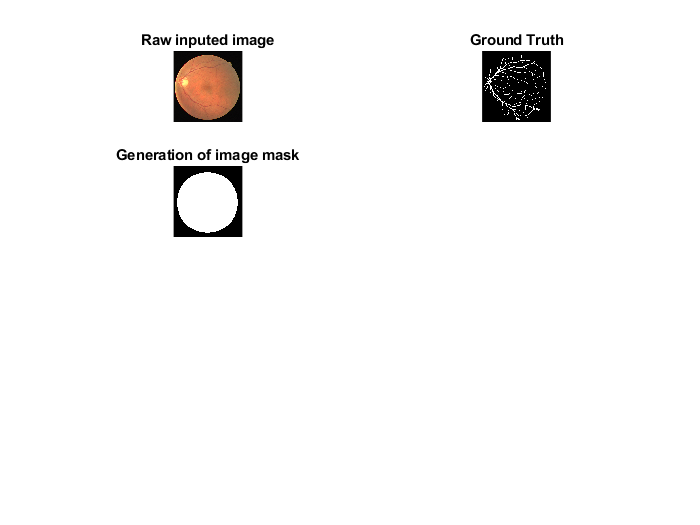

%Generation of image mask
mask = im2bw(inputImage,20/255);
se = strel('diamond',20);               %str. element of dimond type of size 20 (errosion)
erodedmask = im2uint8(imerode(mask,se));    %erroded img
subplot 423
imshow(erodedmask);
title("Generation of image mask");

## Applying gaussian filter to the image

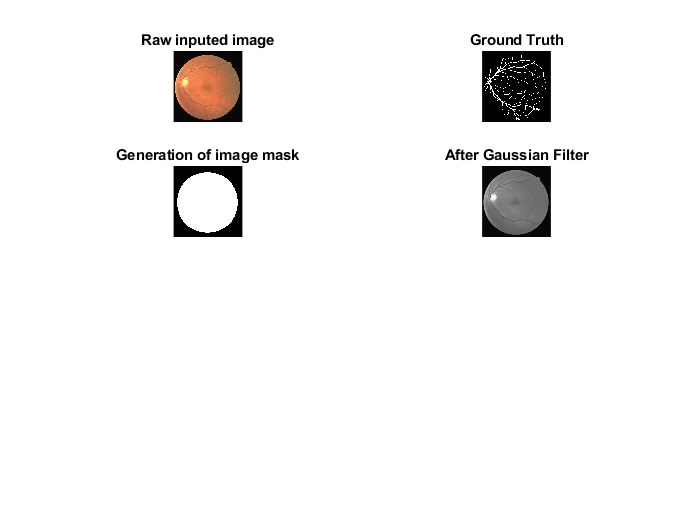

%Apply gaussian filter to the image where s=1.45
img3= imgaussfilt(inputImage(:,:,2) ,1.45);     %sigma st. deviation (s)
subplot 424
imshow(img3);
title("After Gaussian Filter");

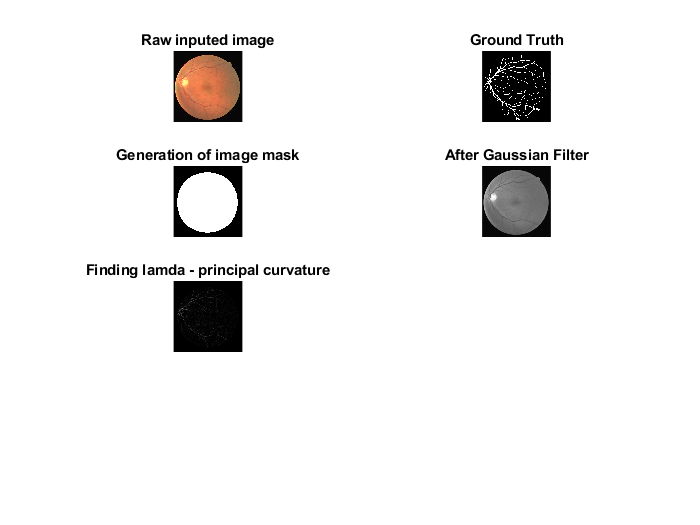

%Finding lamda - principal curvature
%This Function perform region extraction of feature - principal curvature
%of the image which is needed in applying region groeing
%Image : Input Image
%Here we obtain parameters for Hessian metrx in every pixel and find eigen
%values of the hessian matrix using lamdafind function
% Obtain parameters for hessien matrix
[gx, gy] = gradient(double(img3));
[gxx, gxy] = gradient(gx);
[gxy, gyy] = gradient(gy);
[row,col]=size(img3);
lamdaplus = zeros(row,col);
lamdaminus = zeros(row,col);
%finding eigen values of hessian matrix [gxx gxy;gxy gyy]
for r = 1:row
    for c = 1:col
            [lamdaplus(r,c),lamdaminus(r,c)]=lamdafind(gxx(r,c),gyy(r,c),gxy(r,c));
    end
end
%lamda1=min(abs(lamdaplus),abs(lamdaminus));
%obtain the maximum principal curvature 
%lamda2=max(abs(lamdaplus),abs(lamdaminus));
lamda2 = lamdaplus;
maxprincv = im2uint8(lamda2/max(lamda2(:)));
maxprincvmsk = maxprincv.*(erodedmask/255);
subplot 425
imshow(maxprincvmsk);
title("Finding lamda - principal curvature");

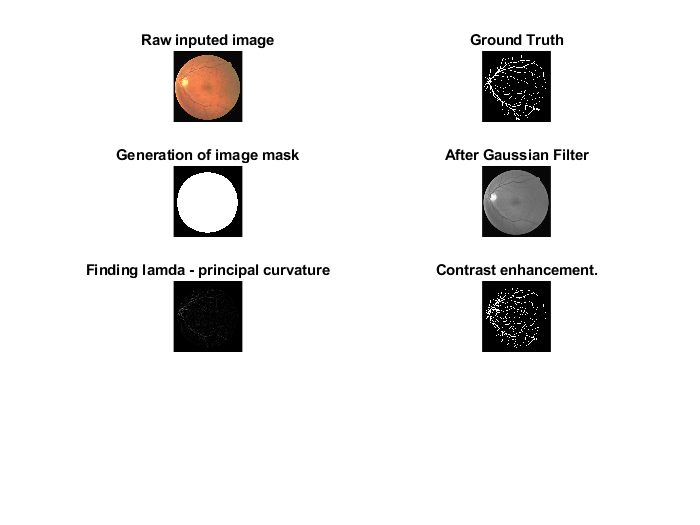

%Contrast enhancement. 
newprI = adapthisteq(maxprincvmsk,'numTiles',[8 8],'nBins',128);
thresh = isodata(newprI);
vessels = im2bw(newprI,thresh);
subplot 426
imshow(vessels);
title("Contrast enhancement.");

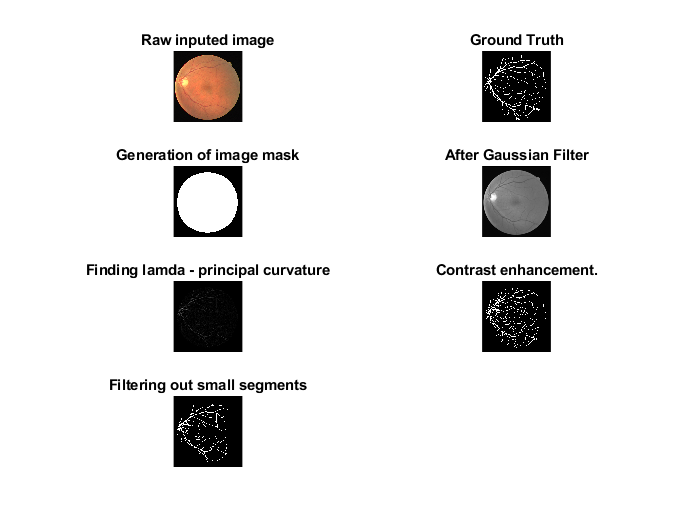

%Filtering out small segments
vessels = bwareaopen(vessels, 200);
segImage = vessels;
subplot 427
imshow(segImage);
title("Filtering out small segments");

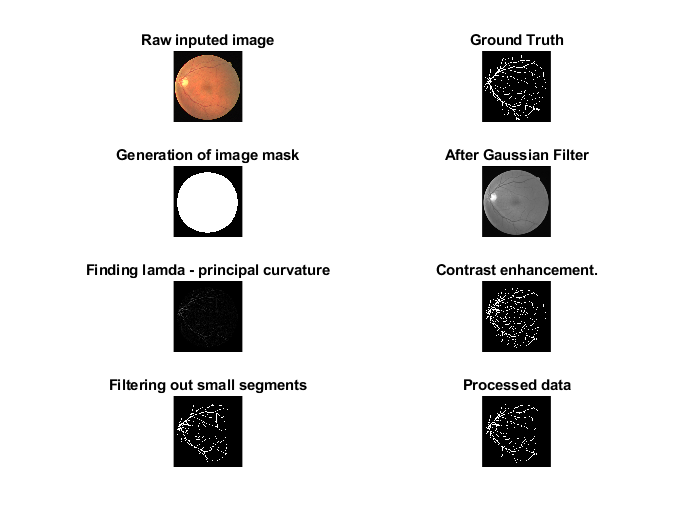

subplot 428
imshow(segImage);
title("Processed data");

## Performing Validation of vessel segmentation

%This function perform validation of vessel segmentation
%manual : Image considered as ground truth.
%Ground truth image is taken from drive data base.
%image : Segmented image output

image=im2uint8(segImage);

%TP - True Positives 
%True positive - Anypixel marked as vessel in both ground truth and
%segemented image

%FP - False positive : Anypixel Market as a vessel pixel in segmented image
%which is marked as background pixel in ground truth

%TN - True Negative : Anypixel marked as backgrounf in both ground truth
%and segmented image

TP=0;
TN=0;
FP=0;


vGT = 0;      
bGT = 0;

[row,col]= size(groundTruth);

for r=1:row
    for c = 1:col
        if groundTruth(r,c)==255
            vGT=vGT+1;
            if image(r,c)==255
                TP=TP+1;
            end

        else
            bGT=bGT+1;
            if image(r,c)==0
                TN=TN+1;
            else
                FP=FP+1;
            end

        end
    end
end

TPR = TP/vGT; %vGT : Number of vessel pixels - Ground truth
FPR = FP/bGT; %vGT : Number of non-vessel pixels - Ground truth

AC= (TP+TN)/(row*col);%Accuracy = (True negative+ True Positive)/all pixels

model = {'Principal curvature'};
A = table(model,TPR,FPR,AC)

A = 1×4 table
             model               TPR        FPR         AC   
    _______________________    _______    ________    _______

    {'Principal curvature'}    0.61887    0.010652    0.96166
